[audio, Fs] = audioread("C:\Users\DELL NEW\Downloads\Perfect - 320Kbps-(Mr-Jat.in).mp3"); 
sound(audio, Fs);
pause(6);
clear sound;
audio = mean(audio, 2);
N = length(audio); 
Y = fft(audio); 
f = (0:N-1) * (Fs/N); 
subplot(231);
plot(f, abs(Y)); 
title('Magnitude Spectrum of Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
t = (0:N-1) /Fs;
subplot(232);
plot(t, audio); 
title('time domain');
xlabel('time ');
ylabel('Magnitude');
fc=1000;
order=6;
[b,a]=butter(order,fc/(Fs/2),'low');
filteredoutput=filter(b,a,audio);
lfiltered=fft(filteredoutput);
subplot(233);
plot(t,filteredoutput);
title('time domain of filtered signal');
xlabel('time ');
ylabel('Magnitude');
subplot(234);
plot(f,abs(lfiltered));
title('Magnitude Spectrum of low pass signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
audiowrite("C:\Users\DELL NEW\Downloads\Perfect - 320Kbps-(Mr-Jat.in).mp3",filteredoutput,Fs)

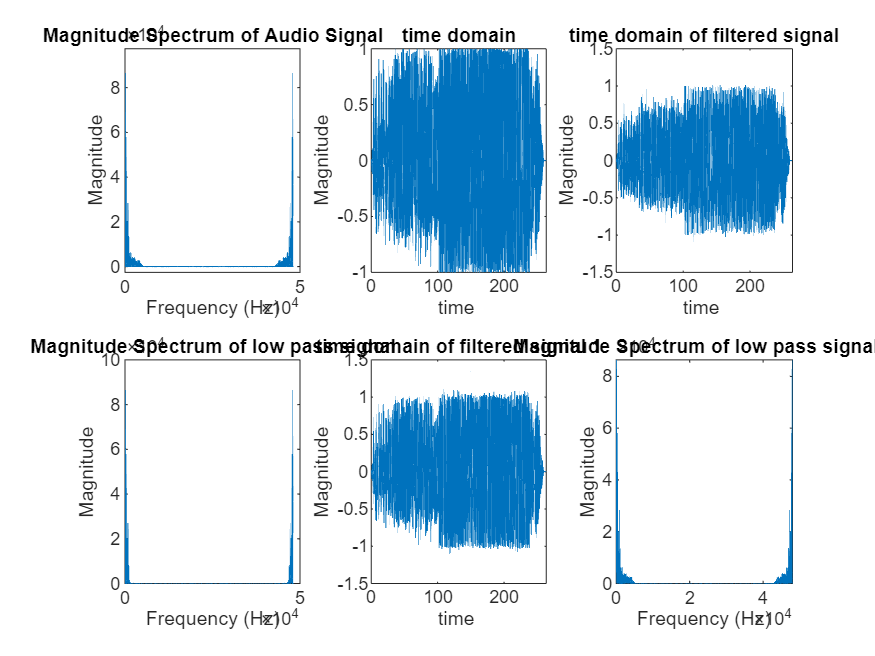

sound(filteredoutput,Fs);
pause(10);
clear sound;
fc1=5000;
order=6;
[b,a]=butter(order,fc1/(Fs/2),'low');
filteredoutput1=filter(b,a,audio);
lfiltered1=fft(filteredoutput1);
subplot(235);
plot(t,filteredoutput1);
title('time domain of filtered signal 1');
xlabel('time ');
ylabel('Magnitude');
subplot(236);
plot(f,abs(lfiltered1));
title('Magnitude Spectrum of low pass signal 1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');axis tight;

subplot(2,3,1)
xlim([0 50000])
ylim([-2607 97393])


audiowrite("C:\Users\DELL NEW\Downloads\Perfect - 320Kbps-(Mr-Jat.in).mp3",filteredoutput1,Fs)

sound(filteredoutput1,Fs);
pause(10);
clear sound;